## Ecualización

load matlab_clasificacion/data_ecu_1.mat

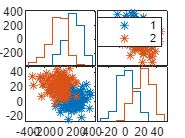

gplotmatrix(X,[],G,[],'*')

- Sería más necesario hacerlo en la característica 1.

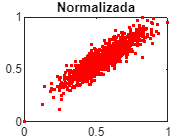

m1 = [1,-1];
s1 = [0.5 0.6; 0.6 0.9];
X = mvnrnd(m1,s1,1000);
X_min1 = min(X(:,1));
X_min2 = min(X(:,2));
X_max1 = max(X(:,1));
X_max2 = max(X(:,2));
X_norm1 = (X(:,1) - X_min1) ./ (X_max1 - X_min1);
X_norm2 = (X(:,2) - X_min2) ./ (X_max2 - X_min2);
figure;
plot(X_norm1,X_norm2,'.',Color="red");
title('Normalizada')

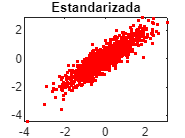


X_mean1 = mean(X(:,1));
X_mean2 = mean(X(:,2));
X_std1 = std(X(:,1));
X_std2 = std(X(:,2));
X_stdzd1 = (X(:,1) - X_mean1) ./ X_std1;
X_stdzd2 = (X(:,2) - X_mean2) ./ X_std2;


figure;
plot(X_stdzd1,X_stdzd2,'.',Color="red");
title("Estandarizada")

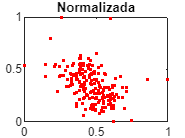

load matlab_clasificacion\data_ecu_2.mat

X_min1 = min(X(:,1));
X_min2 = min(X(:,2));
X_max1 = max(X(:,1));
X_max2 = max(X(:,2));
X_norm1 = (X(:,1) - X_min1) ./ (X_max1 - X_min1);
X_norm2 = (X(:,2) - X_min2) ./ (X_max2 - X_min2);
figure;
plot(X_norm1,X_norm2,'.',Color="red");
title('Normalizada')

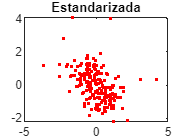


X_mean1 = mean(X(:,1));
X_mean2 = mean(X(:,2));
X_std1 = std(X(:,1));
X_std2 = std(X(:,2));
X_stdzd1 = (X(:,1) - X_mean1) ./ X_std1;
X_stdzd2 = (X(:,2) - X_mean2) ./ X_std2;


figure;
plot(X_stdzd1,X_stdzd2,'.',Color="red");
title("Estandarizada")

- Es menos útil emplear estas técnicas porque los datos están más dispersos.

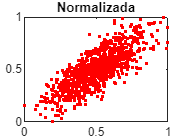

m1 = [1,-1];
s1 = [0.5 0.6; 0.6 1.2];
X = mvnrnd(m1,s1,1000);
X_min1 = min(X(:,1));
X_min2 = min(X(:,2));
X_max1 = max(X(:,1));
X_max2 = max(X(:,2));
X_norm1_a = (X(:,1) - X_min1) ./ (X_max1 - X_min1);
X_norm2_a = (X(:,2) - X_min2) ./ (X_max2 - X_min2);
figure;
plot(X_norm1_a,X_norm2_a,'.',Color="red");
title('Normalizada')

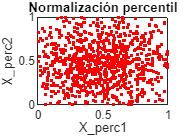

X_norm1 = X(:,1);
X_norm2 = X(:,2);
p5_1  = prctile(X_norm1, 5);
p95_1 = prctile(X_norm1, 95);
mask1 = all(X_norm1 >= p5_1 & X_norm1 <= p95_1, 2);
X_perc1 = X_norm1(mask1, :);
X_perc1 = (X_perc1 - p5_1) ./ (p95_1 - p5_1);

p5_2  = prctile(X_norm2, 5);
p95_2 = prctile(X_norm2, 95);
mask2 = all(X_norm2 >= p5_2 & X_norm2 <= p95_2, 2);
X_perc2 = X_norm2(mask2, :);
X_perc2 = (X_perc2 - p5_2) ./ (p95_2 - p5_2);

figure;
plot(X_perc1, X_perc2, '.', 'Color', 'red');
title('Normalización percentil');
xlabel('X\_perc1');
ylabel('X\_perc2');

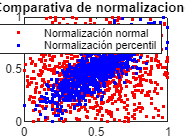

figure
plot(X_perc1, X_perc2, '.', 'Color', 'red')
hold on
plot(X_norm1_a, X_norm2_a, '.', 'Color', 'blue')
title('Comparativa de normalizaciones')
legend('Normalización normal','Normalización percentil');

load matlab_clasificacion/data_trans.mat

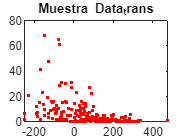

figure;
plot(X(:,1),X(:,2),'.',Color="red");
title('Muestra Data trans')

- Habria que hacer una transformación exponencial o no lineal por al distribución de las muestras.

## Separabilidad de clases

load matlab_clasificacion\data_separ.mat

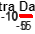

figure;
plot(X(:,1),X(:,2),'.',Color="red");
title('Muestra Data Separ')

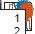

gplotmatrix(X,[],G,[],'*')

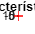

X1 = X(:,1);
X2 = X(:,2);
X3 = X(:,3);
G = [repmat({'Clase 1'},100,1); repmat({'Clase 2'},100,1);repmat({'Clase 3'},100,1);repmat({'Clase 4'},100,1);];
figure
boxplot(X1,G);
title('Característica 1');
ylabel('Distribución observaciones');

- En base a esta característica, la separabilidad entre la clase 4 y el resto es muy sencilla, generando más conflicto entre las 3 primeras.

figure
boxplot(X2,G);
title('Característica 2');
ylabel('Distribución observaciones');

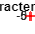

figure
boxplot(X3,G);
title('Característica 3');
ylabel('Distribución observaciones');

- Comparando el resto de características, si evaluamos la característica 3 podemos clasificar con bastante buena calidad la clase 2. La característica 2 no aporta mucha información.

- Las clases 1 y 3 serán más difíciles de clasificar.

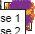

gplotmatrix(X,[],G,[],'*')

- La primera columna se corresponde a la primera característica y asi con el resto.

- La característica 2 me resulta irrelevante y me quedaría con la 1 y 3 para un clasificador.

- La más dificil serían la 1 y 3.

- Eliminar la clase número 3 permitiría una mejor clasificación.